## Naloga 1. Zveza med Bernsteinovo in potenčno bazo.

% polinom v potenčni bazi
p = [4 7 2 8 9 1 4];

b = power2bernstein(p)

b =     4.0000    4.1667    4.9333    6.7000   10.0000   16.6667   35.0000


bernstein2power(b)

ans =     4.0000    7.0000    2.0000    8.0000    9.0000    1.0000    4.0000


power2bernstein(1)

ans = 1

power2bernstein([0 1])

ans =      1     1


power2bernstein([0 0 1])

ans =      1     1     1


power2bernstein([1 0])

ans =      0     1


power2bernstein([0 1 0])

ans =          0    0.5000    1.0000


power2bernstein([0 0 1 0])

ans =          0    0.3333    0.6667    1.0000


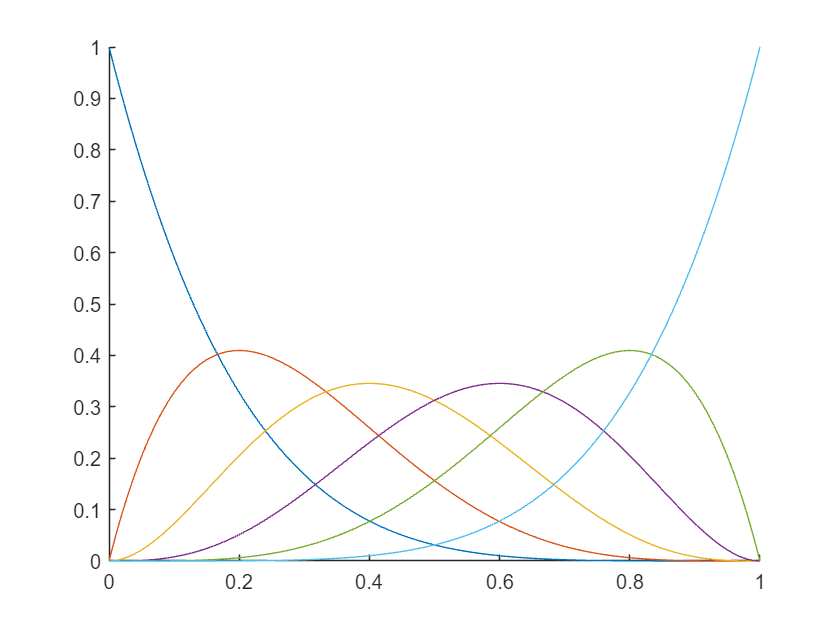

n = 5;
x = linspace(0,1);
clf
hold on
for i = 0:n
    b = zeros(1,n+1);
    b(i+1) = 1;
    plot(x,polyval(bernstein2power(b),x));
end
hold off

## Naloga 2. De Casteljaujev postopek

B = [0 0; 1 2; 3 3; 4 -1; 0 2];
t = linspace(0,1,100);
P = bezier(B,t)

P =          0         0
    0.0410    0.0802
    0.0832    0.1590
    0.1265    0.2365
    0.1709    0.3124
    0.2163    0.3868
    0.2627    0.4595
    0.3099    0.5304
    0.3581    0.5995
    0.4071    0.6668


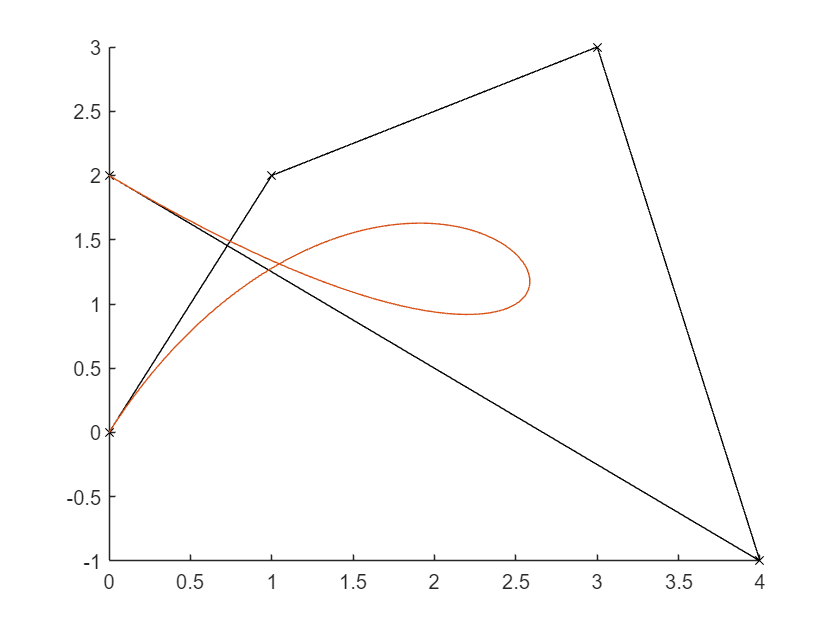

clf
hold on
plot(B(:,1),B(:,2), "Marker","x","Color","black")
plot(P(:,1),P(:,2))
hold off

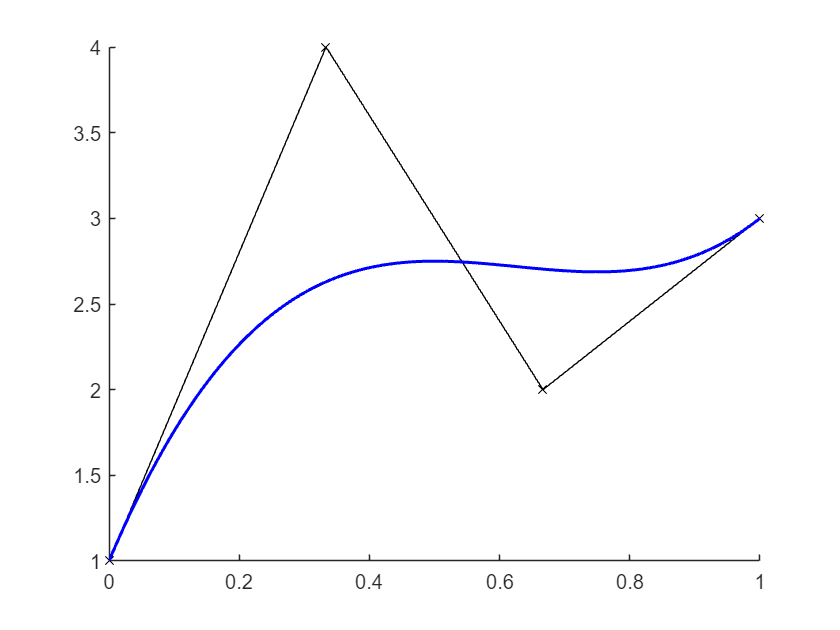

ans =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0101 0.0202 0.0303 0.0404 0.0505 0.0606 0.0707 0.0808 0.0909 0.1010 0.1111 0.1212 0.1313 0.1414 0.1515 0.1616 0.1717 0.1818 0.1919 0.2020 0.2121 0.2222 0.2323 0.2424 0.2525 0.2626 0.2727 0.2828 0.2929 0.3030 … ] (1×100 double)
              YData: [1 1.0894 1.1758 1.2592 1.3397 1.4173 1.4921 1.5642 1.6335 1.7002 1.7643 1.8258 1.8848 1.9413 1.9954 2.0471 2.0965 2.1437 2.1886 2.2313 2.2720 2.3105 2.3471 2.3816 2.4143 2.4450 2.4740 2.5011 2.5266 2.5503 2.5725 … ] (1×100 double)

  Show all propert

clf
B = [1; 4; 2; 3];
plotbezier(B,t,"b")

clf
B = [1,0,3; 4,-4,0; 2,3,0; 0,0,5];
plotbezier(B,t,"b")

ans =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 1.0894 1.1757 1.2591 1.3395 1.4169 1.4915 1.5631 1.6320 1.6980 1.7612 1.8217 1.8794 1.9345 1.9869 2.0367 2.0839 2.1285 2.1705 2.2101 2.2472 2.2819 2.3141 2.3440 2.3715 2.3967 2.4196 2.4403 2.4587 2.4749 2.4890 … ] (1×100 double)
              YData: [0 -0.1179 -0.2291 -0.3339 -0.4324 -0.5246 -0.6107 -0.6909 -0.7653 -0.8340 -0.8971 -0.9547 -1.0071 -1.0543 -1.0964 -1.1337 -1.1661 -1.1939 -1.2171 -1.2360 -1.2506 -1.2610 -1.2675 -1.2701 -1.2689 -1.2641 -1.2558 … ] (1×100 double)
              ZData: [3 2.9100 2.8219 2.7356 2.6512 2.5687 2.4880 2.4093 2.3326 2.2577 2.1848 2.1139 2.0449 1.9779 1.9129 1.8499 1.7890 1.7301 1.6732 1.6184 1.5656 1.5150 1.4664 1.4199 1.3756 1.3334 1.2933 1.255

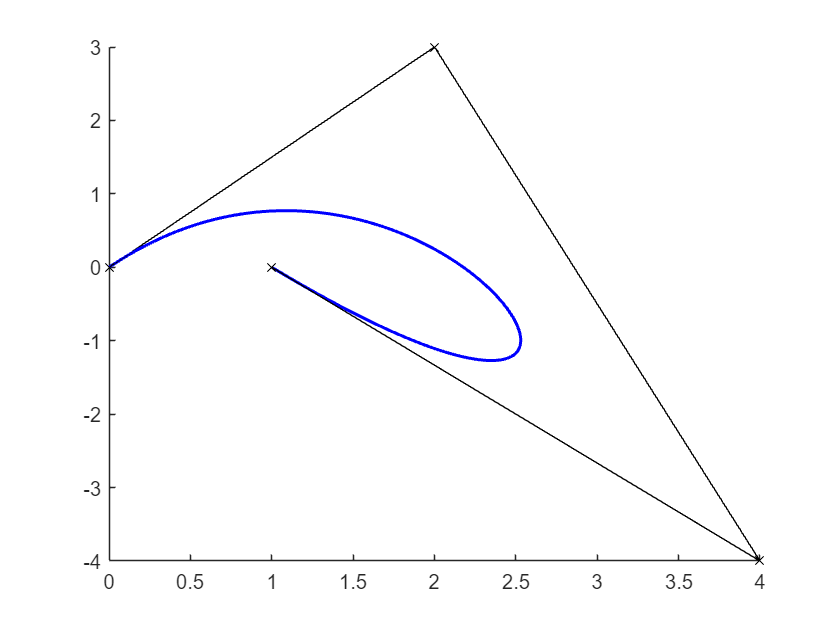

hold off

## Naloga 3. Odvodi Bezierjeve krivulje

t = (0.46:0.01:0.54)';
B = [
    -2/3, -4/5;
    1/3,  1/5;
    0,    0;
    -1/3, 1/5;
    2/3,  -4/5
];
d1b = bezierder(B,1,t);
tab = table();
tab{:,'t'} = t;
tab{:,'x'} = d1b(:,1);
tab{:,'y'} = d1b(:,2);
tab

tab = 9×3 table
     t        x           y    
    ____    ______    _________

    0.46    0.0256      0.19282
    0.47    0.0144      0.14435
    0.48    0.0064     0.096102
    0.49    0.0016     0.048013
     0.5         0            0
    0.51    0.0016    -0.048013
    0.52    0.0064    -0.096102
    0.53    0.0144     -0.14435
    0.54    0.0256     -0.19282


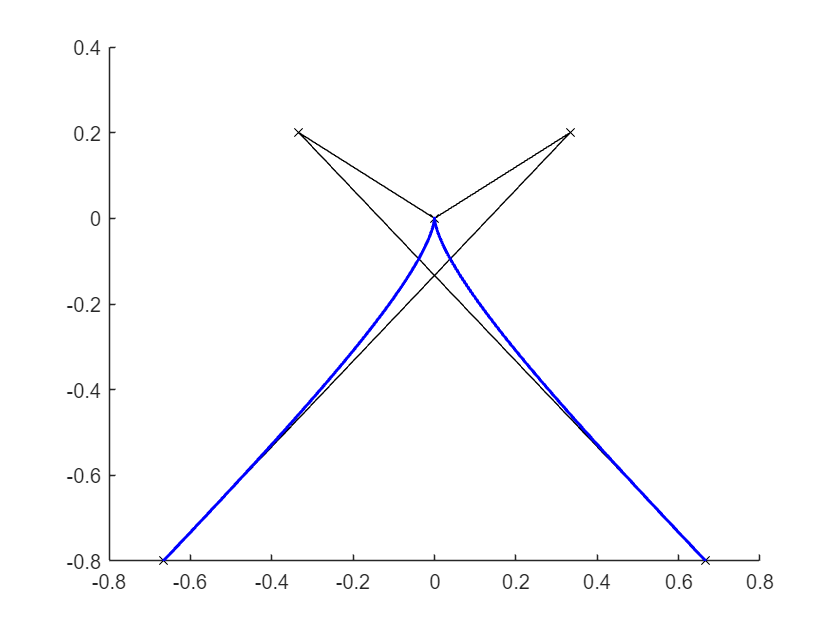

t = linspace(0,1);
[d1b,d1B] = bezierder(B,1,t);
[d2b,d2B] = bezierder(B,2,t);
clf
plotbezier(B,t,"blue");

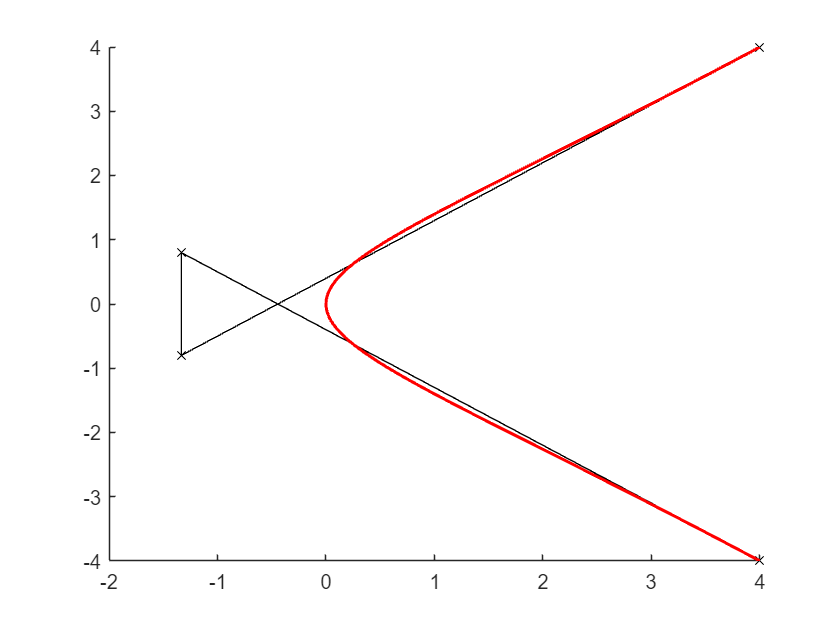

clf
plotbezier(d1B,t, "red");

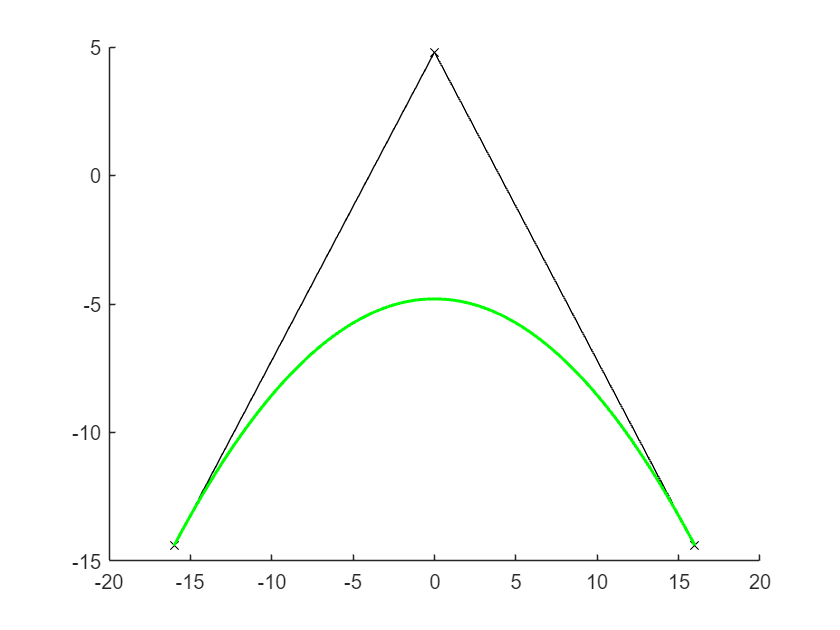

clf
plotbezier(d2B,t, "green");